### Calculate the distribution of $J_{\textrm{ij}}$ based on the face-centered crystal structure of adamantane

% write the coordinates of the grid points, up to 13th nearest neighbors,
% in units of lattice constants a=9.45 Angstrom.
% Due to the symmetry, only half of them need to be calculated.
s=[
     1/2,0,1/2;
    1/2,0,-1/2;
    0,1/2,1/2;
    0,1/2,-1/2;
    1/2,1/2,0;
    1/2,-1/2,0;

    0,0,1;
    1,0,0;
    0,1,0;

    1/2,1,1/2;
    1/2,1,-1/2;
    1,1/2,1/2;
    1,1/2,-1/2;
    1/2,1/2,1;
    1/2,-1/2,1;
    -1/2,1,1/2;
    -1/2,1,-1/2;
    -1,1/2,1/2;
    -1,1/2,-1/2;
    -1/2,1/2,1;
    -1/2,-1/2,1;

    1,1,0;
    1,0,1;
    0,1,1;
    -1,1,0;
    -1,0,1;
    0,-1,1;
% % 
    1/2,0,3/2;
    3/2,0,1/2;
    1/2,3/2,0;
    3/2,1/2,0;
    0,1/2,3/2;
    0,3/2,1/2;
    -1/2,0,3/2;
    -3/2,0,1/2;
    -1/2,3/2,0;
    -3/2,1/2,0;
    0,-1/2,3/2;
    0,-3/2,1/2;

    1,1,1;
    1,-1,1;
    1,1,-1;
    -1,1,1;

    3/2,1/2,1;
    1/2,3/2,1;
    1/2,1,3/2;
    3/2,1,1/2;
    1,3/2,1/2;
    1,1/2,3/2;
    -3/2,1/2,1;
    -1/2,3/2,1;
    -1/2,1,3/2;
    -3/2,1,1/2;
    -1,3/2,1/2;
    -1,1/2,3/2;
    3/2,-1/2,1;
    1/2,-3/2,1;
    1/2,-1,3/2;
    3/2,-1,1/2;
    1,-3/2,1/2;
    1,-1/2,3/2;
    3/2,1/2,-1;
    1/2,3/2,-1;
    1/2,1,-3/2;
    3/2,1,-1/2;
    1,3/2,-1/2;
    1,1/2,-3/2;
% 
    0,0,2;
    0,2,0;
    2,0,0;

    2,1/2,1/2;
    1/2,2,1/2;
    1/2,1/2,2;
    2,-1/2,1/2;
    -1/2,2,1/2;
    -1/2,1/2,2;
    2,1/2,-1/2;
    1/2,2,-1/2;
    1/2,-1/2,2;
    2,-1/2,-1/2;
    -1/2,2,-1/2;
    -1/2,-1/2,2;
    0,3/2,3/2;
    3/2,0,3/2;
    3/2,3/2,0;
    0,3/2,-3/2;
    -3/2,0,3/2;
    -3/2,3/2,0;

    2,1,0;
    1,2,0;
    0,1,2;
    0,2,1;
    1,0,2;
    2,0,1;
    -2,1,0;
    -1,2,0;
    0,-1,2;
    0,-2,1;
    -1,0,2;
    -2,0,1;

    3/2,3/2,1;
    1,3/2,3/2;
    3/2,1,3/2;
    3/2,-3/2,1;
    1,3/2,-3/2;
    3/2,1,-3/2;
    -3/2,3/2,1;
    1,-3/2,3/2;
    -3/2,1,3/2;
    -3/2,-3/2,1;
    1,-3/2,-3/2;
    -3/2,1,-3/2;

    2,1,1;
    1,1,2;
    1,2,1;
    -2,1,1;
    -1,1,2;
    -1,2,1;
    2,-1,1;
    1,-1,2;
    1,-2,1;
    2,1,-1;
    1,1,-2;
    1,2,-1;

    3/2,1/2,2;
    1/2,3/2,2;
    1/2,2,3/2;
    3/2,2,1/2;
    2,3/2,1/2;
    2,1/2,3/2;
    -3/2,1/2,2;
    -1/2,3/2,2;
    -1/2,2,3/2;
    -3/2,2,1/2;
    -2,3/2,1/2;
    -2,1/2,3/2;
    3/2,-1/2,2;
    1/2,-3/2,2;
    1/2,-2,3/2;
    3/2,-2,1/2;
    2,-3/2,1/2;
    2,-1/2,3/2;
    3/2,1/2,-2;
    1/2,3/2,-2;
    1/2,2,-3/2;
    3/2,2,-1/2;
    2,3/2,-1/2;
    2,1/2,-3/2;
    0,1/2,5/2;
    1/2,0,5/2;
    1/2,5/2,0;
    0,5/2,1/2;
    5/2,0,1/2;
    5/2,1/2,0;
    0,-1/2,5/2;
    -1/2,0,5/2;
    -1/2,5/2,0;
    0,-5/2,1/2;
    -5/2,0,1/2;
    -5/2,1/2,0;
    ]; %13th neighbors

a=[9.45, 9.45, 9.45]; %1e-10 m, Angstrom
% gamma_H=267.513*1e6; %rad.s^-1.T^-1
% hbar=1.0545718*1e-34; %J.s
gamma_H=42.58*1e6; %Hz.s^-1.T^-1
h=6.626*1e-34; %J.s
mu=4*pi*1e-7; %T.m.A^-1
c=1/2*mu/(4*pi)*h*gamma_H^2*1e30; %in Hz

rand_times=1e5; %number of random orientations for a powder sample
D=zeros(rand_times,length(s(:,1)));
m_all=zeros(rand_times,3);

u=rand(1,rand_times);
v=rand(1,rand_times);
for j=1:rand_times
        theta=acos(2*u(j)-1); %This is to ensure that every point on the spherical surface is equally sampled.
        phi=2*pi*v(j);        %This is to ensure that every point on the spherical surface is equally sampled.

        m=[sin(theta)*cos(phi),sin(theta)*sin(phi),cos(theta)]; %Orientation of the static magnetic field with respect to the lattice principal axis.

        m_all(j,:)=m;
        Dij=zeros(1,length(s(:,1))); %coupling strength

        for i=1:length(s(:,1))
            ss=s(i,:).*a;
            r=sqrt(sum(ss.^2));
            Dij(i)=c/r^3*(1-3*(sum(ss.*m)/r)^2); %in Hz, coupling strength, 

 Calculated according to $J_{i j} \equiv\left(\mu_0 / 4 \pi\right)\left(\hbar \gamma_{\mathrm{H}}^2 / 2 R_{i j}^3\right)\left(1-3 \cos ^2 \theta_{i j}\right)$

        end
        D(j,:)=Dij;
end

Display the sampling sphere

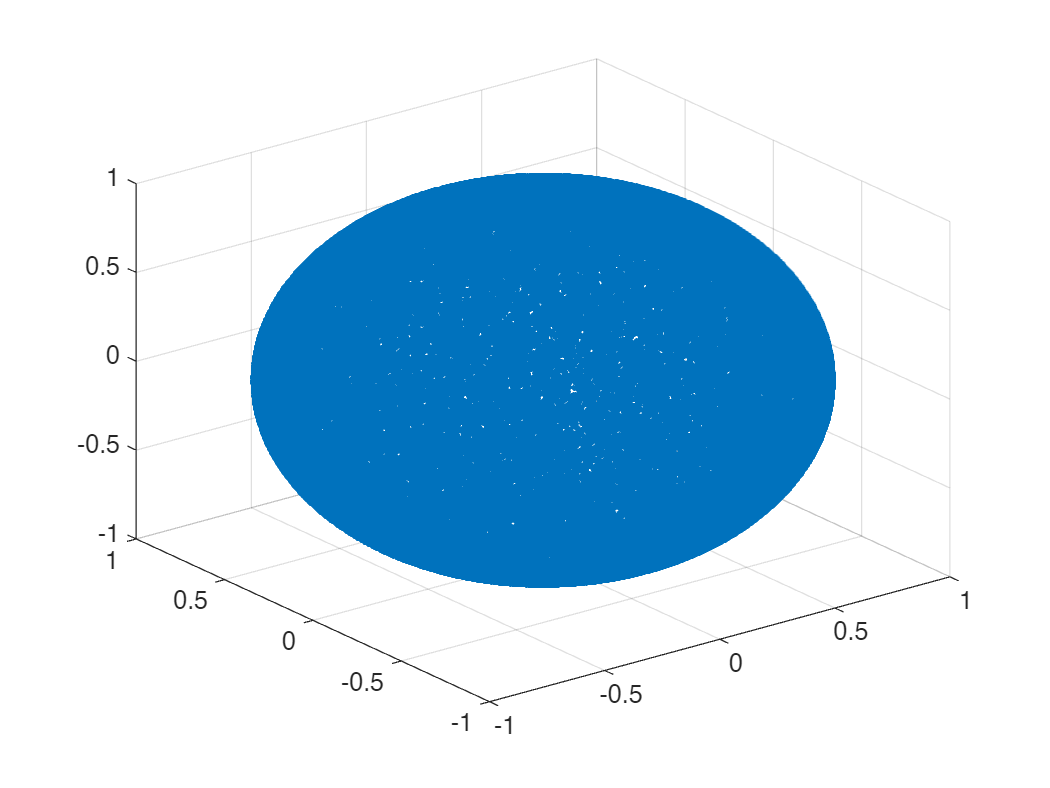

figure()
scatter3(m_all(:,1),m_all(:,2),m_all(:,3),'.')

D

D =  -341.3010  140.1513  145.8659  136.8904  -31.7790  -49.8277   28.8523  -99.9695   71.1171    5.6466   35.3803  -56.6477    4.5469  -21.8779  -24.1873   34.2162    2.1794    2.8070  -59.5391   38.7347   38.7409   -3.9724  -42.6626   18.2332   -6.2285   17.5189   17.1113   -8.8786  -34.9503   14.1475  -20.4780    8.6092   17.1630   16.9589   -9.1128   13.1789  -21.4466    8.1275   16.6813  -10.3066  -11.5325   11.1253   10.7138  -18.6431    3.8534   -0.3784  -11.4805   -0.2575  -11.6517    3.2215
   84.2068 -173.5041   63.1786  190.9834  143.4506 -308.3152   58.2884  -89.8598   31.5714   37.6408   37.5060   16.9569   -7.9088   38.6880   26.1046  -36.8529   -3.9234  -74.0690  -32.8060  -23.3571   22.0210   17.9313   10.5258    7.8973  -38.5394  -21.6880   23.8729   17.9132  -12.0699   17.0372   -7.5388   10.6407    5.2335    4.0829  -25.9002   -7.2071  -31.7831   17.4994   12.0923   13.1926   -1.5026    7.2999  -18.9899    4.2704    8.9202    9.6290    5.6414   10.7778   10.1156  -18

max(D,[],'all')

ans = 201.3179

min(D,[],'all')

ans = -402.6339

[var_D mean_D]=var(D,0,2)

var_D = 1.0e+03 *

    1.3859
    1.4562
    1.1244
    1.4093
    1.4266
    1.5421
    1.5613
    1.6134
    1.6493
    1.5314


mean_D = 1.0e-14 *

   -0.3658
    0.0083
   -0.2220
    0.0380
   -0.3507
    0.0932
    0.7211
   -0.1144
   -0.2356
    0.1088


This verify that the average value of Jij is 0

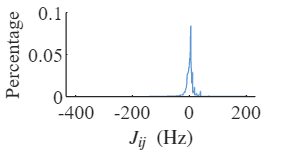

figure()
% histogram(reshape(D,[1,length(D(1,:))*length(D(:,1))]),'BinWidth',2,'Normalization','probability','FaceColor',[157,195,231]/255,'EdgeColor',[157,195,231]/255,'Orientation','vertical')
histogram(reshape(D,[1,length(D(1,:))*length(D(:,1))]),'BinWidth',1,'Normalization','probability','EdgeColor',[95,151,210]/255,'DisplayStyle','stairs')
xlabel('$J_{ij} \ (\mathrm{Hz})$','Interpreter','latex')
ylabel('Percentage')
% title(['b=',num2str(round(m,3))])

fontsize(gcf,8,"points")
set(gcf,'unit','centimeters','position',[10,10,4,2.3]); 
set(gca,"box",'off')
fontname(gcf,"Times New Roman")